# Orientation Tensor Form of Jeffery's Equation

Section 5.1 uses Jeffery's equation to derive an expression for the rate of change of the orientation tensor, Eqn. (5.6):


$$   \dot{\mathbf{A}} 
   = \mathbf{W} \cdot \mathbf{A}   - \mathbf{A} \cdot \mathbf{W}
   +  \xi ( \mathbf{D} \cdot \mathbf{A}  +\mathbf{A}  \cdot \mathbf{D}
   - 2 \mathbf{D} : \mathbb{A})$$


For this example, the fourth-order tensor is approximated using the quadratic closure,


$$\mathbb{A}_{ijkl} = A_{ij} A_{kl}$$


These equations are implemented in `AdotJeffQuad`.  Following the example in Section 5.1.2, here is how the built-in Matlab function `ode45` is used to integrate the equation.  Note that the initial orientation `Avzero` is in $6 \times 1$ column vector form.  The matrix of results `Av` from `ode45` has a row for each time and the columns correspond to the six contracted components of the orientation tensor.  

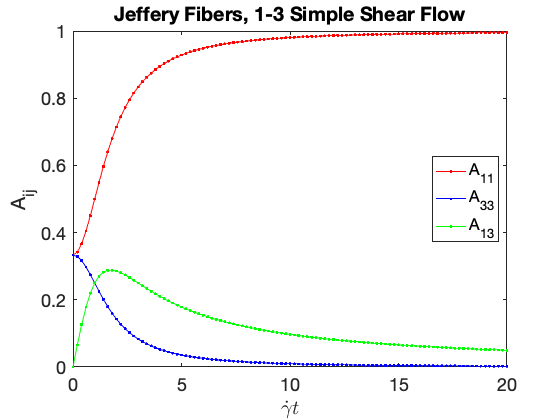

%% Example solution of the orientation tensor equations
% Problem specification
L = zeros(3,3); L(1,3) = 1;  % Velocity gradient, 1--3 simple shear flow 
xi = 1;                      % Particle shape factor
tspan = 0:0.20:20;           % Solution times
Avzero = tens2vec(eye(3)/3); % Initial condition: isotropic orientation
% ODE integration options
options = odeset('RelTol', 1e-6, 'AbsTol', 1e-9);
% Integrate the ODE
[t, Av] = ode45(@(t,Av) AdotJeffQuad(Av,L,xi), tspan, Avzero, options);

% Simple plot of results
figure
plot(t,Av(:,1),'r.-', t,Av(:,3),'b.-', t,Av(:,5),'g.-')
set(gca, 'FontSize', 18)
xlabel('$\dot{\gamma} t$', 'Interpreter', 'LaTeX') 
ylabel('A_{ij}')
legend('A_{11}', 'A_{33}', 'A_{13}', 'Location', 'East')
title('Jeffery Fibers, 1-3 Simple Shear Flow')

This matches Fig. 5.1(a).